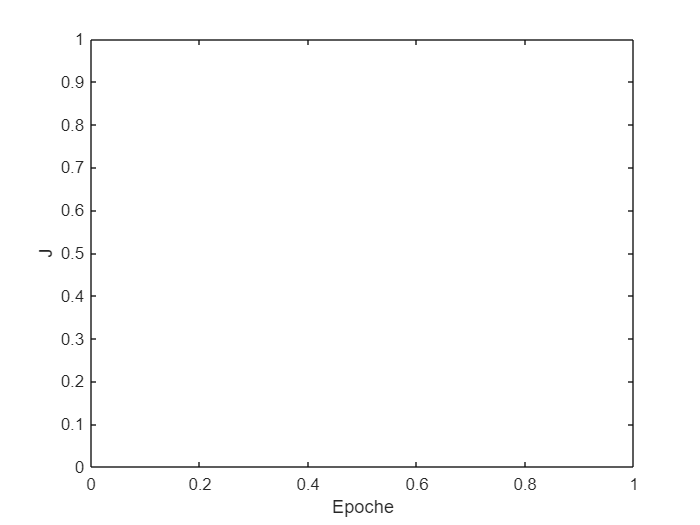

clc
clear
close all
load("../../Segnale nullo/25MHz/data_iddataC.mat");
% input = data.OutputData(1:1000);
input = 0:0.01:20;
input = sin(input);



[y_est,J,W] = neuralnetwork(input,30,0.2,4,20);


stem(J)
ylabel('J')
xlabel('Epoche')

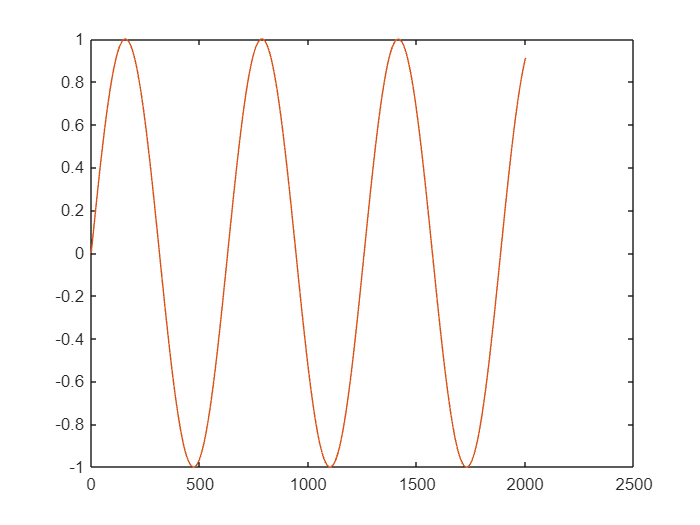

figure,
plot(y_est)
hold on
plot(input)

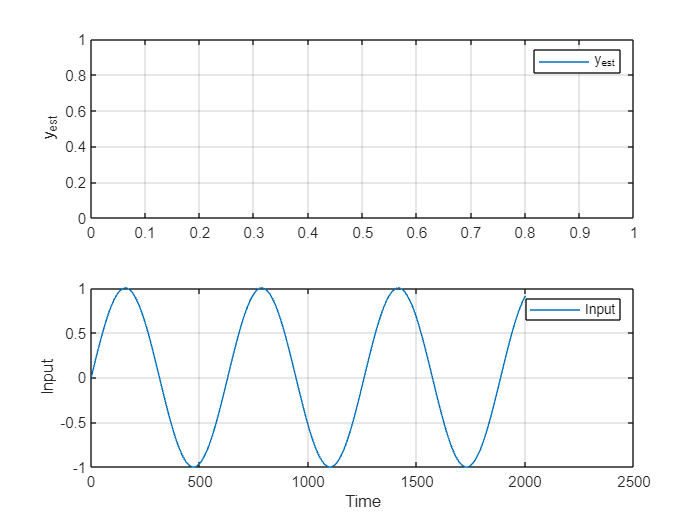

figure;
subplot(2,1,1);
plot(y_est);
grid on;
ylabel('y_{est}');
legend('y_{est}');

subplot(2,1,2);
plot(input);
grid on;
ylabel('Input');
xlabel('Time');

legend('Input');

function alpha = neuron(input, weights,type)
    
    n = sum(input.*weights,1);
    switch(type)
        case 'hidden'
            alpha = (1-exp(-2*n))/(1+exp(-2*n));
        case 'output'
            alpha = n;
    end
end
function layerOutput = neuralLayer(input, weights, numNeurons,type)
    for i = 1:numNeurons
        layerOutput(i,:) = neuron(input, weights, type);
    end
end
function [output,J,weights] = neuralnetwork(input,epocs,learning_rate,hidden_layers,neurons_hiddenlayers)
    
    weights = randn(neurons_hiddenlayers,hidden_layers+1);
    for p = 1:epocs
        %% Feed forward
        for t = 1:numel(input)
            input_hidden{1} = input(:,t);
            outputhidden{1} = neuralLayer(input_hidden{1}, weights(:,1), neurons_hiddenlayers,'hidden');
            input_hidden{2} = outputhidden{1};
            i = 2;
            while(i <= hidden_layers)
                outputhidden{i} = neuralLayer(input_hidden{i}, weights(:,i), neurons_hiddenlayers,'hidden');
                input_hidden{i+1} = outputhidden{i};
                i = i + 1;
            end
            output(:,t) = neuralLayer(input_hidden{i}, weights(:,i), 1,'output');
            error(:,t) = input(:,t) - output(:,t);
            %% Backpropagation-output layer
            
            weights(:,end) = weights(:,end) + learning_rate*outputhidden{end}*error(t);
            %% Backpropagation-hidden layer
            for i = hidden_layers:-1:1
                dFun = 1 - tanh(sum(weights(:,i).*input_hidden{i}))^2;
                weights(:,i) = weights(:,i) - learning_rate * input_hidden{i} * dFun * sum(-error(t) * weights(:,end)');
            end
        end
        J(p) = (1/numel(input))*sum(error.^2);
    end
end
